# **Vision Artificial. GIEC.**

# **Sistemas de Vision Artificial. GIC.**

**Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel. **

**  Departamento de Electrónica. Universidad de Alcalá. SPAIN.**

**Autor(es): Franck Michael Fierro Chicaiza**

**Fecha: 01/10/2023**

# Tema 2. Corrección de transformaciones geométricas. 

Para corregir el efecto de las transformaciones geométricas debemos calcular la matriz que nos permite cambiar la posición de los píxeles de entrada y ubicarlos en las posiciones de salida correctas/no distorsionadas. En Matlab la función que utilizamos para ello es [`tform = estgeotform2d(matchedPoints1,matchedPoints2,transformType)`](https://www.mathworks.com/help/releases/R2023a/vision/ref/estgeotform2d.html?browser=F1help#d124e211773?browser=F1help)`, `que estima la matriz necesaria para hacer coincidir los `matchedPoints1` de la imagen de entrada con los `matchedPoints2` de la imagen de salida. En este ejercicio, le proporcionaremos nosotros como variable los valores de `matchedPoints2` donde deben ubicarse los píxeles de la imagen de salida después de la transformación. 

# Corrección de giro

Para calcular la matriz necesaria para corregir una imagen rotada (con o sin escalado) solamente necesitamos 2 puntos. En este caso seleccionaremos los dos puntos más alejados de los anillos de saturno y el código está preparado para girarlos y colocarlos en horizontal.

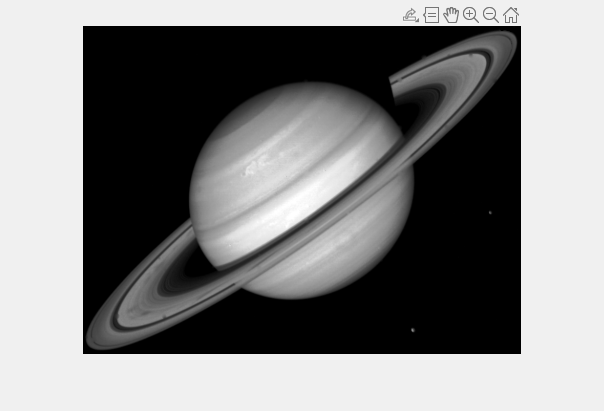

clc
clear all;
close all;

% Read original image.
I = imread('.\imagenes\saturn.tif');

% NOTE: impixel 
% Use normal button clicks to select pixels. 
% Press Backspace or Delete to remove the previously selected pixel. 
% To add a final pixel and finish pixel selection in one step, press shift-click, or right-click or double-click. 
% To finish selecting pixels without adding a final pixel, press Return.
figure
[x, y, P] = impixel(I);

% Puntos obtenidos de la imagen
srcPoints = [x y]  

srcPoints =     11   316
   428    11


% Posición de los extremos de los anillos para que queden en posición horizontal
dstPoints = [100 100; ...
            300 100]; 

% Estimacion de la transformacion de la perspectiva
[tform,inlierIndex,status] = estgeotform2d(srcPoints, dstPoints,'similarity')

tform =   simtform2d with properties:

    Dimensionality: 2
             Scale: 0.3871
     RotationAngle: 36.1823
       Translation: [168.7810 -1.2513]
                 R: [2×2 double]
                 A: [3×3 double]


inlierIndex = 2×1 logical array
   1
   1


status = int32
0

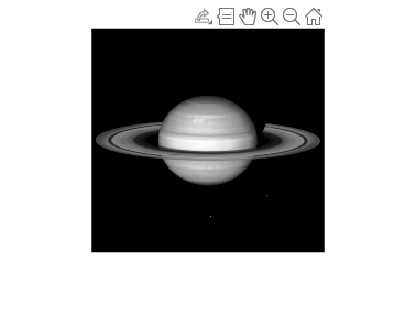

destino = imwarp(I,tform);  % Transformacion en la imagen
figure; imshow(destino);

Modifique los valores de los puntos de destino para que la imagen final quede con orientación distinta y muéstrela.

% Valores para cambiar la orientacion
dstPoints = [100 0; 100 200];   
[tform,inlierIndex,status] = estgeotform2d(srcPoints, dstPoints,'similarity')

tform =   simtform2d with properties:

    Dimensionality: 2
             Scale: 0.3871
     RotationAngle: 126.1823
       Translation: [201.2513 68.7810]
                 R: [2×2 double]
                 A: [3×3 double]


inlierIndex = 2×1 logical array
   1
   1


status = int32
0

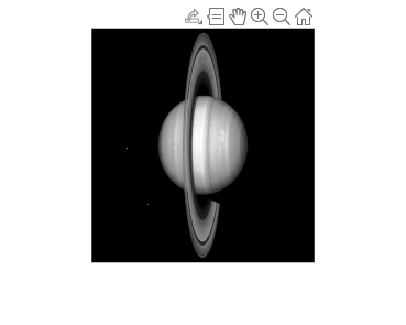

destino = imwarp(I,tform);
figure; imshow(destino);

**Comentario: Después de probar diferentes puntos de salida, he notado que, al tratarse de una rotación, la imagen ajusta su orientación. Además, el tamaño de la imagen también varía en función de los puntos de salida seleccionados.**

# Corrección de la Perspectiva con Homografía

Para corregir la perspectiva de un objeto es necesario estimar la transformación de la perspectiva. Cuatro pares de puntos correspondientes son suficientes para recuperar una transformación de perspectiva entre dos imágenes. El objetivo de esta práctica es corregir la perspectiva de la carta de la imagen "`card.jpg`",

Se pide: 

- Cargue la imagen "`card.jpg`". Haga clic en las cuatro esquinas de la tarjeta para obtener los primeros cuatro puntos utilizando la función `impixel`. Nota: utilice el siguiente orden para obtener los cuatro puntos: 1) Esquina superior izquierda, 2) Esquina superior derecha, 3) Esquina inferior derecha, 4) Esquina inferior izquierda.

- Calcule los cuatro puntos de la carta de póquer sin distorsión de perspectiva, teniendo en cuenta que una carta de póquer tiene un tamaño de 100` mm` por `150 mm` aproximadamente.

- Estime la transformación de la perspectiva utilizando la función `estgeotform2d` sabiendo que en este caso el tipo de transformación es `"``projective``".` 

- Aplicar la transformación de perspectiva utilizando la función `imwarp`.

- Muestre la carta no distorsionada.

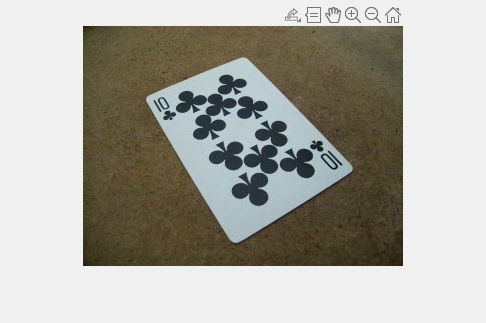

% 1. Cargamos la imagen
I = imread('.\Practica2\card.jpg');

% 2. Calculamos los puntos de la carta de poquer a la salida
dstPoints = [0 0; 100 0; 100 150; 0 150];

% 3. Capturamos los puntos de entrada de la carta y estimamos la
% transformacion de perspectiva
figure
[x, y, P] = impixel(I);

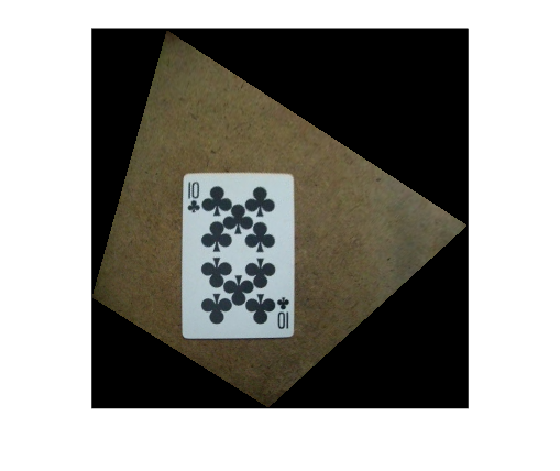


srcPoints = [x y];
[tform,inlierIndex,status] = estgeotform2d(srcPoints, dstPoints,'projective');

% 4. Aplicamos la transformacion de perspectiva
destino = imwarp(I,tform);

% 5. Mostramos el resultado
figure; imshow(destino);

**Comentario: En este caso, podemos observar cómo la imagen se distorsiona para ajustar los cuatro puntos seleccionados como entrada a los puntos de salida, logrando así modificar el objeto deseado.**